In this example we will consider the following non linear system:


$$\dot{x} = \pmatrix{x_2 \cr sin(x_1) - c \, x_2} + \pmatrix{0 \cr cos(x_1)} u$$


If we linearise this system around its operation point $(\bar{x}, \bar{u}) = (0,0)$ we get the following system:


$$\dot{x} = \pmatrix{0 & 1 \cr 1 & -c} x + \pmatrix{0\cr 1}u$$


We will now see if we are able to retreive this linearised system by using data from the non linear system around the operation point. To generate the data we will use the [`[t,y] = ode45(odefun,tspan,y0)`](https://nl.mathworks.com/help/matlab/ref/ode45.html#d122e895996) provided by Matlab as well as a manual implementation of the Euler method.

c = 1;
u = 0;
sys_eq_em  = @(x)    [x(2) ; sin(x(1)) - c * x(2)] + [0 ; cos(x(1)) * u];
sys_eq_ode = @(t, x) [x(2) ; sin(x(1)) - c * x(2)] + [0 ; cos(x(1)) * u];

For this example we will consider a constant input for the system. This is because we are atempting to find a descrete time system adhering to the data generated by a continuous time system. Hence due to zero order hold we need our input to be constant. In this case we choose to provide no input.

Since a linearisation is only valid around the equilibrium point we need to sample our data there as well. Hence we will pick an intitial condition close to zero.

x0 = [1e-3 ; 1e-3];

## Generating data

As noted earlier we will use the euler method to generate the state data of the non linear dynamics. We want our timestep to be as small as posible for better preformance of the method:

dt_em = 1e-3;             % Time step
t_final = 20;             % final time
t_em = 0:dt_em:t_final;
T = size(t_em, 2); % Number of measurements

X_em = zeros(2,T+1); % Used for storing the state data
X_em(:,1) = x0;

for iter = 1:T
    X_em(:, iter + 1) = X_em(:, iter) + dt_em * sys_eq_em(X_em(:, iter));
end

plot(0:dt_em:t_final + dt_em, X_em)
title('Approximation of nonlinear system')
xlabel('Time')
hold on

We wil also use the [`[t,y] = ode45(odefun,tspan,y0)`](https://nl.mathworks.com/help/matlab/ref/ode45.html#d122e895996) method to generate comparative data.

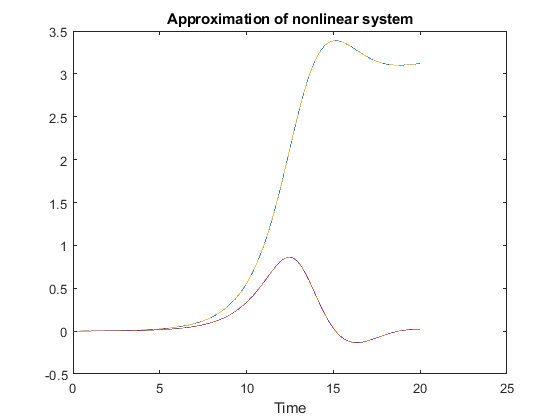

dt_ode = 1e-3;
[t_ode, X_ode] = ode45(sys_eq_ode, 0:dt_ode:t_final, x0);
t_ode = t_ode';
X_ode = X_ode';

plot(t_ode, X_ode, '--');
hold off

As we can see both apoximations behave similarly

### Finding the A matrix

Since we did not consider input for this example, we are not able to identify the $B$ matrix of the system. However we might still be able to indentify the linearisation of the $A$ matrix. To do this we will start by looking at the first 2 datapoints (the minimal amount) and checking if they are informative for system identification. After this we will repeat this process with more data points and see if there is a point where the data is not informative for system identification.

% Euler case
for idx = 2:1000 %size(X_em,2)
    if ~isInformIdentification(X_em(:,1:idx))
        fprintf('The data is not informative for system identification using %d points (Euler)\n', idx);
    end
end

The data is not informative for system identification using 2 points (Euler)



% Ode case
for idx = 2:1000 %size(X_ode,2)
    if ~isInformIdentification(X_ode(:,1:idx))
        fprintf('The data is not informative for system identification using %d points (Ode)\n', idx);
    end
end

The data is not informative for system identification using 2 points (Ode)


As we can see the data is informative for system identification when we have 3 data points all the way up to using all of them. We will now take a look at the resulting $A$ matrix obtained from these computations. Note that the matrices returned by `isInformIdentification(X)` are in descrete time with time step `dt_em` or `dt_ode`. Hence to see how accurate they are, we need to convert them back to continuous time. For now we will consider 2 cases, only the minimal amount of data points (close to the equilibrium point) and all data points

[~, A_min_em] = isInformIdentification(X_em(:,1:3));
sys_d_min_em = ss(A_min_em, [0;0], eye(2), 0, dt_em);
disp('A_min matrix after transforming it to continuous time (Euler):')

A_min matrix after transforming it to continuous time (Euler):


disp(d2c(sys_d_min_em).A)

  -0.000500333242048   1.000500666771539
   1.000500166412752  -1.001000666744380




[~, A_min_ode] = isInformIdentification(X_ode(:,1:3));
sys_d_min_ode = ss(A_min_ode, [0;0], eye(2), 0, dt_ode);
disp('A_min matrix after transforming it to continuous time (ode):')

A_min matrix after transforming it to continuous time (ode):


disp(d2c(sys_d_min_ode).A)

   0.000000002500686   0.999999997484049
   0.999999496443175  -0.999999663079329




[~, A_all_em] = isInformIdentification(X_em);
sys_d_all_em = ss(A_all_em, [0;0], eye(2), 0, dt_em);
disp('A_all matrix after transforming it to continuous time (Euler):')

A_all matrix after transforming it to continuous time (Euler):


disp(d2c(sys_d_all_em).A)

   0.000014628350255   0.999964395553739
  -0.029257047776394   0.071204859931650




[~, A_all_ode] = isInformIdentification(X_ode);
sys_d_all_ode = ss(A_all_ode, [0;0], eye(2), 0, dt_ode);
disp('A_all matrix after transforming it to continuous time (ode):')

A_all matrix after transforming it to continuous time (ode):


disp(d2c(sys_d_all_ode).A)

  -0.000001004683411   1.000047901230146
  -0.029246543812270   0.071209565447934




A_true = [0 1;1 -c];
disp('A_true matrix for the continuous time linearisasion:')

A_true matrix for the continuous time linearisasion:


disp(A_true)

     0     1
     1    -1



If we compare this to the linearisation made by hand we can see that using minimal data we identify the linearisation of a non linear model when using the data.

### Error of the A matrix

We will now take a look at the error between the true linearisation and our approximation based on the data. To do this we will consider the sum of the absolute value of the element wise error. We will calculate this error for all cases from minimal data to all data.

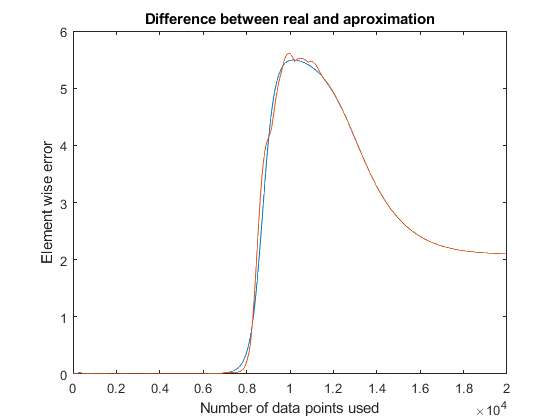

loop_interval = 3:40:size(X_em,2);
error_array_em = [];
error_array_ode = [];
for idx = loop_interval
    [bool_em, A_d_em] = isInformIdentification(X_em(:,1:idx));
    if bool_em
        A_c_em = d2c(ss(A_d_em, [0;0], eye(2), 0, dt_em)).A;
        error_array_em = [error_array_em sum(sum(abs(A_true - A_c_em)))];
    end
    [bool_ode, A_d_ode] = isInformIdentification(X_ode(:,1:idx));
    if bool_ode
        A_c_ode = d2c(ss(A_d_ode, [0;0], eye(2), 0, dt_ode)).A;
        error_array_ode = [error_array_ode sum(sum(abs(A_true - A_c_ode)))];
    end
end

plot(loop_interval, error_array_em, loop_interval, error_array_ode);
title('Difference between real and aproximation');
xlabel('Number of data points used');
ylabel('Element wise error');

If we take a look at the plot then we can see that our accuracy decrease starts around `5500` measurements, which corresponds to `t=5.5` on the plot of the nonlinear function. As we can see in the plot of the function, around `t=5.5` is when the function 'stops' being linear. If we zoom in on the plot we can see that around 5500 data points the accuracy of the Euler method stops decreasing and starts to increase. However, the accuracy of the `ode45` method is all over the place. This is most likely the case due to the algorithm being designed for a dynamic time interval instead of a fixed time interval as we used.

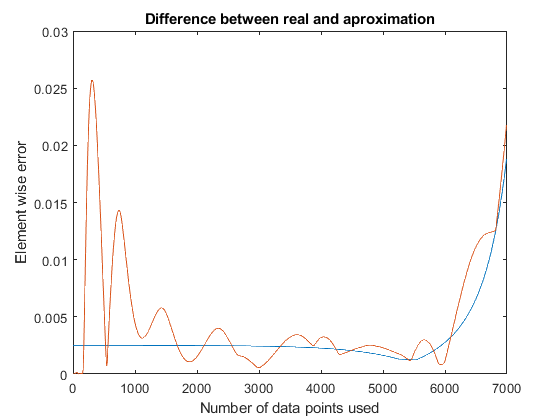

loop_interval = 3:10:7000;
error_array_em = [];
error_array_ode = [];
for idx = loop_interval
    [bool_em, A_d_em] = isInformIdentification(X_em(:,1:idx));
    if bool_em
        A_c_em = d2c(ss(A_d_em, [0;0], eye(2), 0, dt_em)).A;
        error_array_em = [error_array_em sum(sum(abs(A_true - A_c_em)))];
    end
    [bool_ode, A_d_ode] = isInformIdentification(X_ode(:,1:idx));
    if bool_ode
        A_c_ode = d2c(ss(A_d_ode, [0;0], eye(2), 0, dt_ode)).A;
        error_array_ode = [error_array_ode sum(sum(abs(A_true - A_c_ode)))];
    end
end

plot(loop_interval, error_array_em, loop_interval, error_array_ode);
title('Difference between real and aproximation');
xlabel('Number of data points used');
ylabel('Element wise error');

If we look closely at the error of Euler method than we can seethat  there is a wierd bend around 5500 data points. If we look at the plot of the non linear system then we can see that both variables start becomming 'non linear' at different times. We can verify this by looking at the sum of the absolute elementwise error for each column instead of for the while matrix

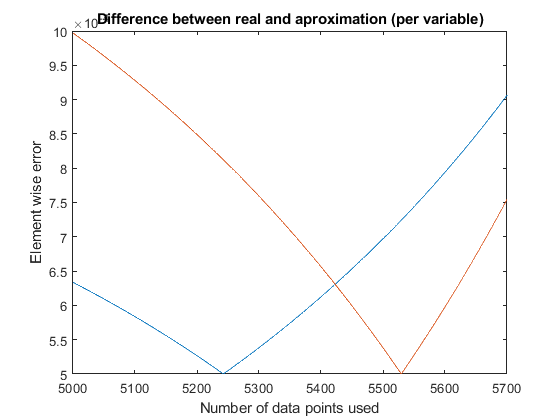

loop_interval = 5000:5700;
error_array = [];
for idx = loop_interval
    [bool, A_d] = isInformIdentification(X_em(:,1:idx));
    if bool
        A_c = d2c(ss(A_d, [0;0], eye(2), 0, dt_em)).A;
        error_array = [error_array sum(abs(A_true - A_c))'];
    end
end
plot(loop_interval, error_array);
title('Difference between real and aproximation (per variable)');
xlabel('Number of data points used');
ylabel('Element wise error');

As we can expected both variable 'turn nonlinear' at different points.

### Moving the starting condition

We will now consideder what happence to the accuracy of the linearisation when we move our starting position closer to the equilibrium point. To do this we will use the `ode45` method with a time setp of `0.1`.

dt_ode = 1e-2;

init_con = [1e-1 ];%1e-2 1e-3 1e-4 1e-5 1e-6 1e-7]';
tablestruct.ic   = init_con;
tablestruct.err  = zeros(size(init_con,1), 1);
tablestruct.iter = zeros(size(init_con,1), 1);

for idx = 1:size(init_con,1)
    % Generate data
    [t_ode, X_ode] = ode45(sys_eq_ode, 0:dt_ode:20, [init_con(idx) ; init_con(idx)]);
    t_ode = t_ode';
    X_ode = X_ode';
    
    min_err = inf;
    min_err_it = nan;
    
    % Check for the closest A matrix and the corresponding error
    for iter = 3:size(X_ode,2)
        [bool, A_d] = isInformIdentification(X_ode(:,1:iter));
        if bool
            A_c = d2c(ss(A_d, [0;0], eye(2), 0, dt_ode)).A;
            err_new = sum(sum(abs(A_true - A_c)));
            if err_new < min_err
                min_err = err_new;
                tablestruct.err(idx)  = err_new;
                tablestruct.iter(idx) = iter;
            end
        end
    end
end

struct2table(tablestruct)

ans = 1×3 table
    ic             err            iter
    ___    ___________________    ____

    0.1    0.00859376666019494     3  


As we can see the error is decreasing if we pick an initial condition close to the equilibrium point. However, when we use the `ode45` method to generate our data points, we can see that our best solution is in the first few iterations. As we saw with the Euler solution however, its solution is much more stable and predictable. It does however need a lot more data points to be effective.

## Non zero input

We will now repeat some of the calculations using a unit input for our system. The reason why we are interested in these results is because we will be able to infere the B matrix when we use non zero data.

A_true = [0 1 ; 1 -c];
B_true = [0 ; 1];

u = 0.1;
sys_eq_ode = @(t, x) [x(2) ; sin(x(1)) - c * x(2)] + [0 ; cos(x(1)) * u];

This will result in the following plot of the non linear system.

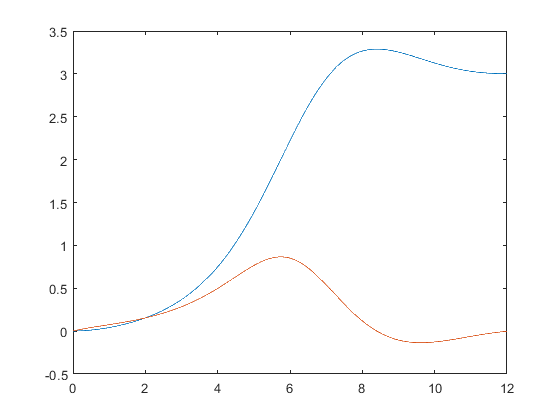

dt_ode = 1e-2;
t_final = 12;
x0 = [1e-3 1e-3];
[t_ode, X_ode] = ode45(sys_eq_ode, 0:dt_ode:t_final, x0);
t_ode = t_ode';
X_ode = X_ode';
U_ode = u * ones(1, size(X_ode,2) - 1);
plot(t_ode, X_ode);

As we can see on the plot, due to the reletively high input provided to the system the system does not behave very linear around zero. However, due to our small time step this will not be a problem.

n = 4;
[b, A, B] = isInformIdentification(X_ode(:, 1:(n+1)), U_ode(:, 1:n));
disp('The calculated system from minimal data converted to continuous time:');

The calculated system from minimal data converted to continuous time:


sys_c = d2c(ss(A,B,eye(2),0,dt_ode));
disp(sys_c.A);

   0.000257273089148   0.999992100660295
   0.999458214399784  -0.999986612809696



fprintf('The total difference between A and A_true: %d\n', sum(sum(abs(sys_c.A - A_true))))

The total difference between A and A_true: 8.203452e-04


disp(sys_c.B);

  -0.000002469689126
   1.000004741900265



fprintf('The total difference between B and B_true: %d\n', sum(sum(abs(sys_c.B - B_true))))

The total difference between B and B_true: 7.211589e-06


A next step might be to reduce the step size to get a more accurate aproximation. However this is not always the case:

dt_arr = [1e-1 1e-2 1e-3 1e-4 1e-5 1e-6]';
x0 = [1e-3 1e-3];
A_err_ar = ones(size(dt_arr));
B_err_ar = ones(size(dt_arr));

for idx = 1:size(dt_arr,1)
    dt = dt_arr(idx);
    [t, X] = ode45(sys_eq_ode, 0:dt:(dt*100), x0);
    X = X';
    U = u * ones(1, size(X,2) - 1);
    
    [bool, A, B] = isInformIdentification(X(:, 1:(n+1)), U(:, 1:n));
    if bool
        sys_c = d2c(ss(A,B,eye(2),0,dt));
        A_err_ar(idx) = sum(sum(abs(sys_c.A - A_true)));
        B_err_ar(idx) = sum(sum(abs(sys_c.B - B_true)));
    end
end
disp('    time step    -    error A    -    error B')

    time step    -    error A    -    error B


disp([dt_arr A_err_ar B_err_ar])

   0.100000000000000   0.012964470449889   0.000029312664319
   0.010000000000000   0.000820345219372   0.000007211589391
   0.001000000000000   0.000109986925410   0.000000595991316
   0.000100000000000   0.000104907655363   0.000000534732914
   0.000010000000000   0.003621496411579   0.000027309894895
   0.000001000000000   2.859399023909486   0.016523310467887



As we can see the error  will decrease if we decrease the step size, until we reach a certain point. After that point the data points are to close together and do not describe enough of the trejectory to construct an accurate aproximation. If we wat to increase the accuracy even more, we need to pick a starting condition closer to the equilibrium point. We will pick our best preforming step size, namely `dt=1e-4` for this test.

x0_arr = [1e-1 1e-2 1e-3 1e-4 1e-5 1e-6]';
dt = 1e-4;
A_err_ar = ones(size(dt_arr));
B_err_ar = ones(size(dt_arr));

for idx = 1:size(dt_arr,1)
    x0 = [x0_arr(idx) x0_arr(idx)];
    [t, X] = ode45(sys_eq_ode, 0:dt:(dt*100), x0);
    X = X';
    U = u * ones(1, size(X,2) - 1);
    
    [bool, A, B] = isInformIdentification(X(:, 1:(n+1)), U(:, 1:n));
    if bool
        sys_c = d2c(ss(A,B,eye(2),0,dt));
        A_err_ar(idx) = sum(sum(abs(sys_c.A - A_true)));
        B_err_ar(idx) = sum(sum(abs(sys_c.B - B_true)));
    end
end
disp('    initial condition    -    error A    -    error B')

    initial condition    -    error A    -    error B


disp([dt_arr A_err_ar B_err_ar])

   0.100000000000000   0.055013728551130   0.008184310510483
   0.010000000000000   0.001188092107075   0.000062795376490
   0.001000000000000   0.000104907655363   0.000000534732914
   0.000100000000000   0.000010189848143   0.000000005257456
   0.000010000000000   0.000000993376587   0.000000000047786
   0.000001000000000   0.000000159547557   0.000000000002372



As we can see, if we pick our time step small enough, but not to small and our initial condition close to the equilibruim point, we are able to construct the linearisation around the equilibruim point directly from the data.